% Get labels for each image.
load trainingHoGData.mat;


 

classifier = fitcecoc(hogFeatures, trainingLabels);

testingFolder = 'C:\Users\rickf\Google Drive\Greenstand\SVM\Testing';

imds = imageDatastore(testingFolder,'IncludeSubfolders',true,'LabelSource','foldernames');

imdsAug = augmentedImageDatastore([277,277],imds,'OutputSizeMode','centercrop' );

 

hogTestFeatures = zeros(length(imds.Files),length(hogFeatures));

for i = 1:length(imds.Files)
     dataTable = readByIndex(imdsAug,i);
     img = dataTable{1,1}{1};
     img = SegmentGreenWithOtsu(img);   
    [testFeatures , ~] = extractHOGFeatures(img,'CellSize', [8,8]);
    hogTestFeatures(i,:) = testFeatures;
end

     

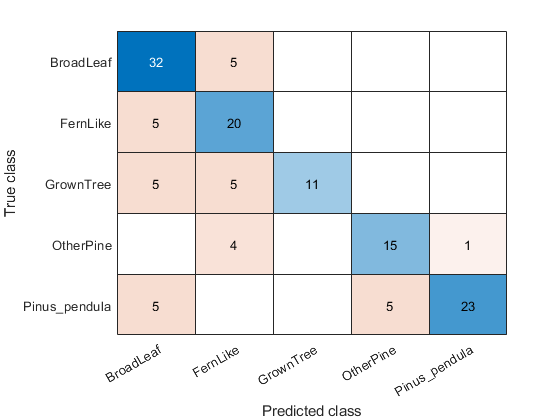

% Make class predictions using the test features.
predictedLabels = predict(classifier, hogTestFeatures);
testLabels = imds.Labels;
% Tabulate the results using a confusion matrix.
[confMat,order] = confusionmat(testLabels, predictedLabels);

figure
cm = confusionchart(confMat,order);